# **Wireless Communications **

# **Computer Assignment 2 **

## **Soroush Mesforush Mashhad - 810198472**

**Important, In this project I have used the bit_gen function **

**which I designed in the DCS lab course instructed by Dr. Olfat**

### **Question 1**

**Part a)**

clc
clear all
a = 1;
N=1e4;
SNR_dB = linspace(-20, 20, N/8);
ForLen = length(SNR_dB);
x = 2*bit_gen(N,2)-1;
Pe = zeros(1,ForLen);
for i = 1:ForLen
   H = sqrt(1/2).*(randn(N,1)+1j*randn(N,1));
   N0 = a^2./10.^(SNR_dB(i)/10);
   W = sqrt(N0/2)*(randn(N,1) + 1j*randn(N,1));
   Y = H.*x + W;
   Delta = real(Y);
   Erroneous = Delta.*x<0;
   Pe(i) = sum(Erroneous,'all')./N;
end
Pe

Pe =     0.5059    0.5107    0.5043    0.4939    0.5024    0.4939    0.5057    0.4989    0.5000    0.4987    0.5004    0.5077    0.4989    0.5063    0.4971    0.4900    0.5051    0.5065    0.4984    0.4895    0.5105    0.5036    0.5058    0.5018    0.4914    0.4930    0.4898    0.5127    0.4967    0.4993    0.4955    0.4966    0.4955    0.5022    0.4972    0.5044    0.4964    0.4971    0.4991    0.5038    0.4977    0.4938    0.5045    0.4958    0.4984    0.5057    0.5008    0.5031    0.5033    0.5015


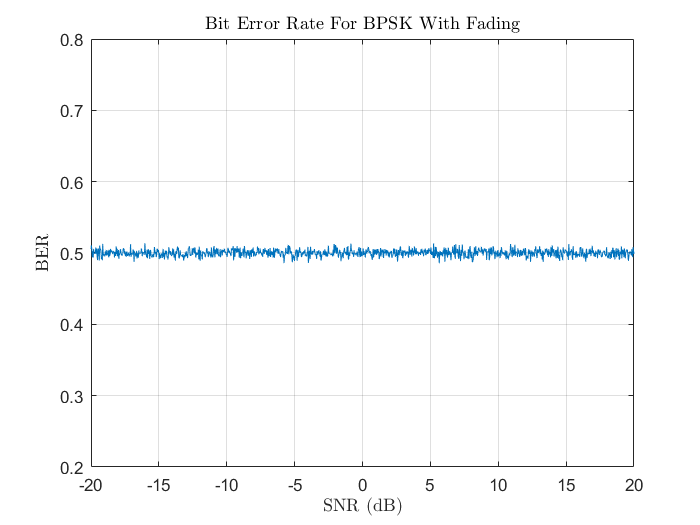

plot( SNR_dB, Pe);
xlabel('SNR (dB)','interpreter','latex');
ylabel('BER','interpreter','latex');
grid on
ylim([0.2 0.8])
title('Bit Error Rate For BPSK With Fading','interpreter','latex');

**Part b)**

clc
clear all
a = 1;
N=1e4;
SNR_dB = linspace(-20, 20, N/8);
ForLen = length(SNR_dB);
x = 2*bit_gen(N,2)-1;
Pe = zeros(1,length(SNR_dB));
for i = 1:ForLen
   N0 = a^2./10.^(SNR_dB(i)/10);
   W = sqrt(N0/2)*(randn(N,1) + 1j*randn(N,1));
   Y = x + W;
   Delta = real(Y);
   Erroneous = Delta.*x<0;
   Pe(i) = sum(Erroneous)./N;
end
Pe

Pe =     0.4382    0.4459    0.4434    0.4460    0.4451    0.4469    0.4392    0.4345    0.4458    0.4384    0.4545    0.4390    0.4420    0.4371    0.4459    0.4315    0.4357    0.4429    0.4381    0.4341    0.4438    0.4398    0.4397    0.4436    0.4452    0.4468    0.4429    0.4417    0.4343    0.4378    0.4378    0.4378    0.4505    0.4303    0.4331    0.4302    0.4259    0.4420    0.4362    0.4346    0.4314    0.4337    0.4351    0.4317    0.4375    0.4259    0.4289    0.4327    0.4400    0.4304


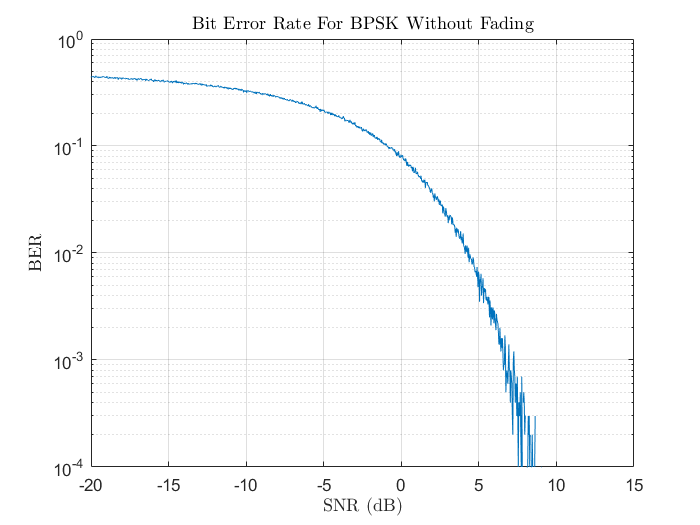

semilogy( SNR_dB, Pe);
xlabel('SNR (dB)','interpreter','latex');
ylabel('BER','interpreter','latex');
grid on
title('Bit Error Rate For BPSK Without Fading','interpreter','latex');

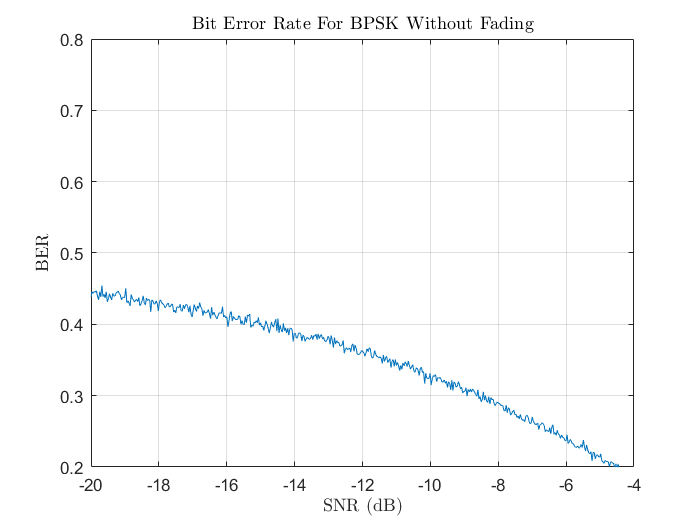

plot( SNR_dB, Pe);
xlabel('SNR (dB)','interpreter','latex');
ylabel('BER','interpreter','latex');
grid on
ylim([0.2 0.8]);
title('Bit Error Rate For BPSK Without Fading','interpreter','latex');

**Question 2**

**Part a)**

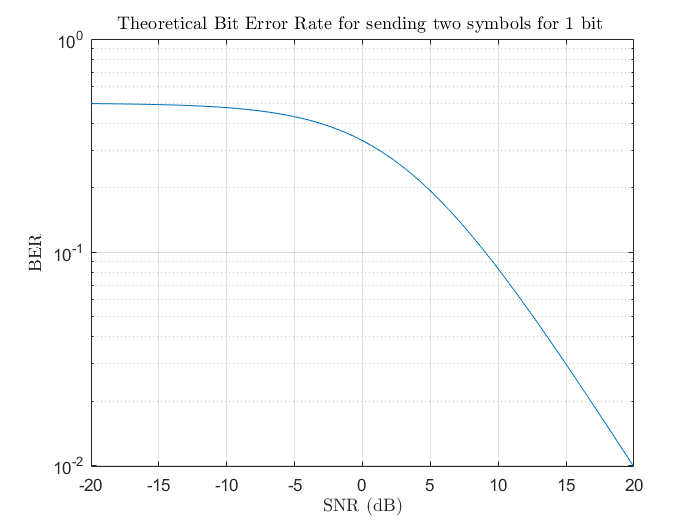

clc
clear all
N=1e4;
SNR_dB = linspace(-20, 20, N/8);
Pe = 1./(2+(10.^(SNR_dB/10)));
semilogy(SNR_dB,Pe );
save pe2parta1.mat 'Pe'
grid on
xlabel(" SNR (dB)",'interpreter','latex');
ylabel("BER",'interpreter','latex');
title("Theoretical Bit Error Rate for sending two symbols for 1 bit ",'interpreter','latex');

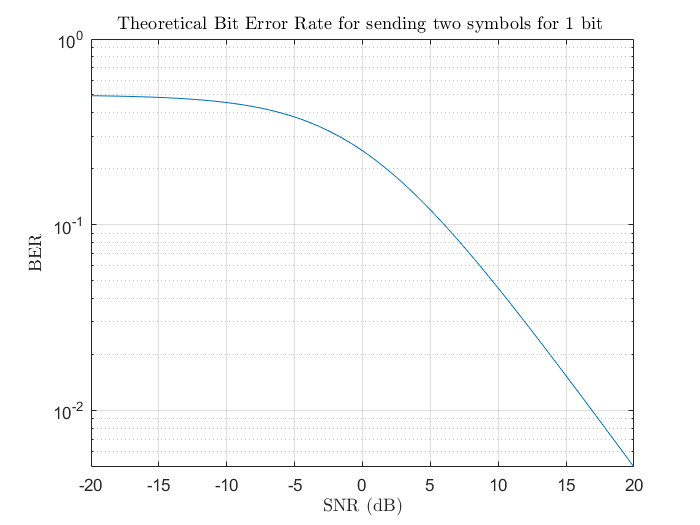

%Second Approach for thoery
clc
clear all
N=1e4;
SNR_dB = linspace(-20, 20, N/8);
Pe = 1./(2+(2*10.^(SNR_dB/10)));
semilogy(SNR_dB,Pe );
save pe2parta2.mat 'Pe'
grid on
xlabel(" SNR (dB)",'interpreter','latex');
ylabel("BER",'interpreter','latex');
title("Theoretical Bit Error Rate for sending two symbols for 1 bit ",'interpreter','latex');

**Part b)**

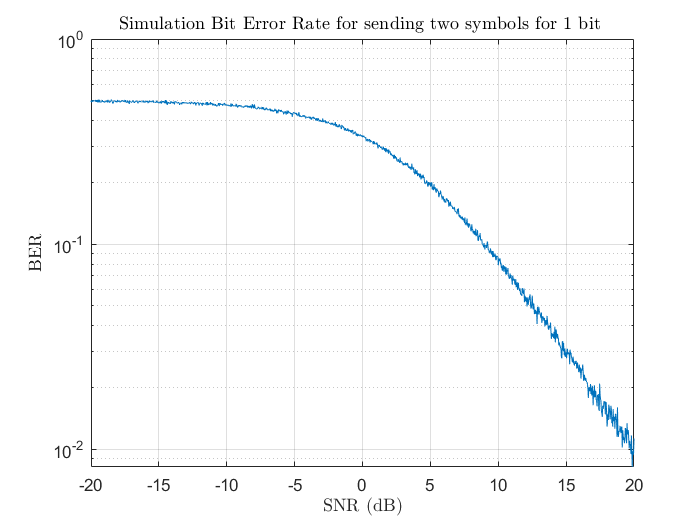

clc
clear all
a = 1;
N=1e4;
SNR_dB = linspace(-20, 20, N/8);
ForLen = length(SNR_dB);
x = bit_gen(N,2);
xuse = zeros(N,2);
for j=1:N
    if x(j)==1
        xuse(j,1)=0;
        xuse(j,2)=a;
    end
    if x(j)==0
        xuse(j,1)=a;
        xuse(j,2)=0;
    end
end
Pe = zeros(1,length(SNR_dB));
for i = 1:ForLen
   N0 = a^2./10.^(SNR_dB(i)/10);
   H = sqrt(1/2).*(randn(N,2)+1j*randn(N,2));
   W = sqrt(N0/2)*(randn(N,2) + 1j*randn(N,2));
   Y = H.*xuse + W;
   Delta = abs((Y(:,1))).^2 - abs((Y(:,2))).^2;
   Erroneous = Delta.*(2*x - 1)>0;
   Pe(i) = sum(Erroneous)./N;
end
save pe2partb.mat 'Pe'
figure
semilogy(SNR_dB,Pe );
grid on
xlabel(" SNR (dB)",'interpreter','latex');
ylabel("BER",'interpreter','latex');
title("Simulation Bit Error Rate for sending two symbols for 1 bit ",'interpreter','latex');

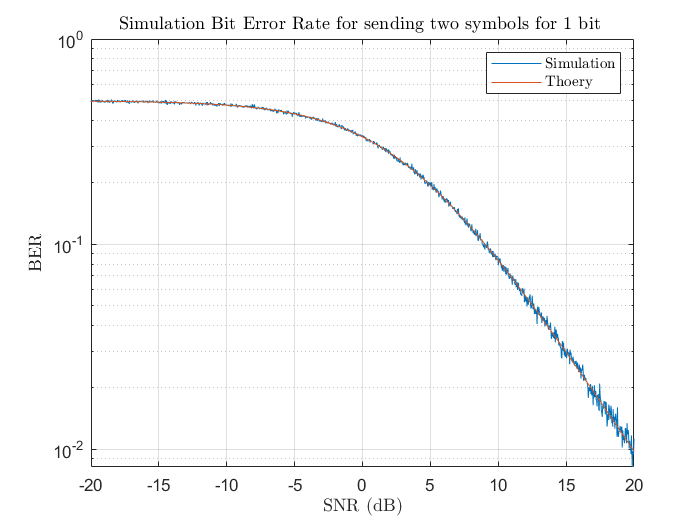

 Peavg2a = load('pe2parta1.mat');
 Peavg2a = Peavg2a.Pe;
 figure
 semilogy(SNR_dB,Pe,SNR_dB,Peavg2a);
 grid on
 xlabel(" SNR (dB)",'interpreter','latex');
 ylabel("BER",'interpreter','latex');
 title("Simulation Bit Error Rate for sending two symbols for 1 bit ",'interpreter','latex');
 legend('Simulation','Thoery','interpreter','latex')
 hold off

**Question 3**

**Part a)**

clc
clear all
a = 1;
N=1e4;
SNR_dB = linspace(-20, 20, N/8);
Peavg = (1/2) .* (1-sqrt(10.^(SNR_dB./10)./(1+10.^(SNR_dB./10))))
save peavg3parta.mat 'Peavg'
semilogy(SNR_dB,Peavg );
grid on

Peavg =     0.4502    0.4501    0.4499    0.4497    0.4495    0.4493    0.4491    0.4490    0.4488    0.4486    0.4484    0.4482    0.4480    0.4478    0.4476    0.4474    0.4473    0.4471    0.4469    0.4467    0.4465    0.4463    0.4461    0.4459    0.4457    0.4455    0.4453    0.4451    0.4449    0.4447    0.4445    0.4443    0.4441    0.4439    0.4437    0.4435    0.4433    0.4431    0.4429    0.4426    0.4424    0.4422    0.4420    0.4418    0.4416    0.4414    0.4412    0.4410    0.4407    0.4405


xlabel(" SNR (dB)",'interpreter','latex');
ylabel("PeAvg",'interpreter','latex');
title("Theory Average Error probability ",'interpreter','latex');

**Part b)**

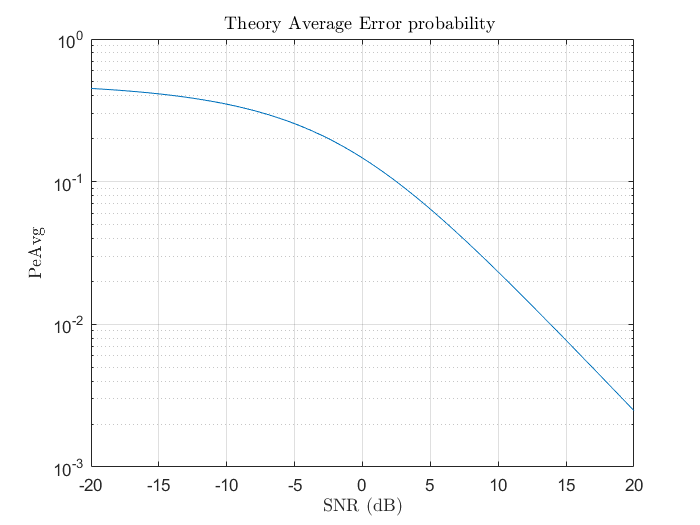

clc
clear all
a = 1;

N=1e4;
SNR_dB = linspace(-20, 20, N/8);
ForLen = length(SNR_dB);
x = 2* bit_gen(N,2) -1 ;
Pe = zeros(1,length(SNR_dB));
for i = 1:ForLen
   H = sqrt(1/2)*(randn(N,1)+1j*randn(N,1));
   N0 = a^2./10.^(SNR_dB(i)/10);
   W = sqrt(N0/2)*(randn(N,1) + 1j.*randn(N,1));
   Y = H.*x + W;
   Yprime = real(Y.*conj(H)./abs(H));
   Erroneous =Yprime.*x<0;
   Pe(i) = sum(Erroneous)./N;
end

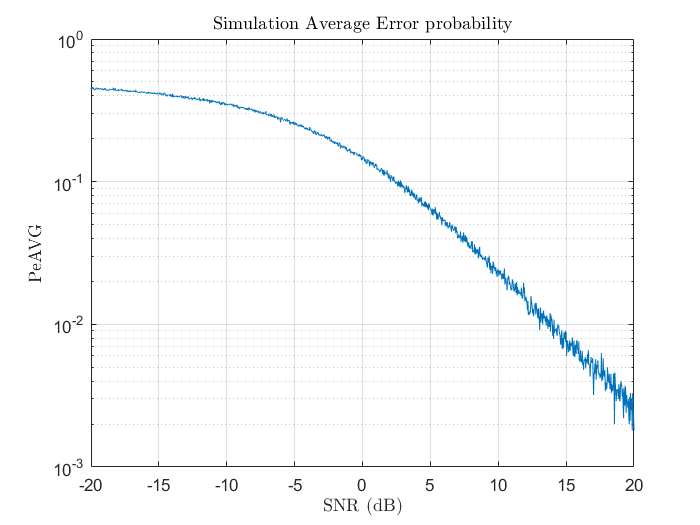

semilogy( SNR_dB, Pe);
xlabel('SNR (dB)','interpreter','latex');
ylabel('PeAVG','interpreter','latex');
grid on
title('Simulation Average Error probability','interpreter','latex');

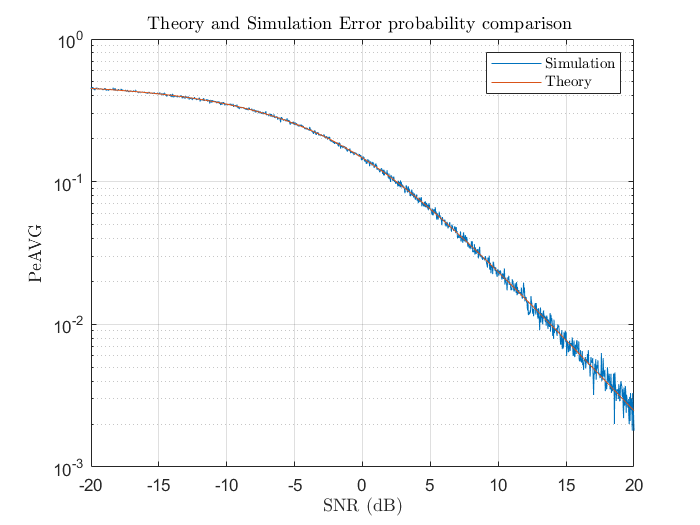

Peavg3a = load('peavg3parta.mat');
Peavg3a = Peavg3a.Peavg;
figure
semilogy(SNR_dB,Pe,SNR_dB,Peavg3a);
grid on
xlabel(" SNR (dB)",'interpreter','latex');
ylabel("PeAVG",'interpreter','latex');
title("Theory and Simulation Error probability comparison ",'interpreter','latex');
legend('Simulation','Theory','interpreter','latex')
hold off

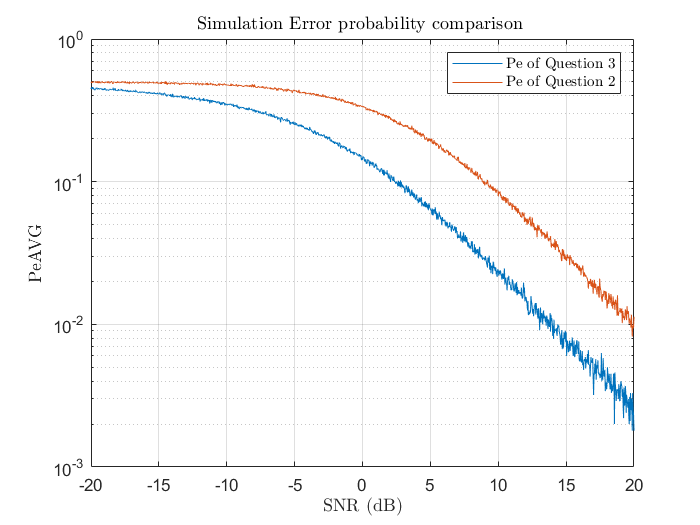

Pe2 = load('Pe2partb.mat');
Pe2 = Pe2.Pe;
figure
semilogy(SNR_dB,Pe,SNR_dB,Pe2 );
grid on
xlabel(" SNR (dB)",'interpreter','latex');
ylabel("PeAVG",'interpreter','latex');
title("Simulation Error probability comparison ",'interpreter','latex');
legend('Pe of Question 3','Pe of Question 2','interpreter','latex')
hold off

dif = abs(Pe2(1250) - Pe(1250))

dif = 0.0095

10*log10(dif)

ans = -20.2228

**Question 4**

**Part a)**

clc
clear all
a = 1;
N=1e4;
SNR_dB = linspace(-20, 20, N/8);

Peavg = (1/2) .* (1-sqrt(10.^(SNR_dB./10)./(2+10.^(SNR_dB./10))))

Peavg =     0.4647    0.4646    0.4645    0.4643    0.4642    0.4641    0.4639    0.4638    0.4637    0.4635    0.4634    0.4633    0.4631    0.4630    0.4629    0.4627    0.4626    0.4625    0.4623    0.4622    0.4620    0.4619    0.4618    0.4616    0.4615    0.4613    0.4612    0.4611    0.4609    0.4608    0.4606    0.4605    0.4603    0.4602    0.4601    0.4599    0.4598    0.4596    0.4595    0.4593    0.4592    0.4590    0.4589    0.4587    0.4586    0.4584    0.4583    0.4581    0.4579    0.4578


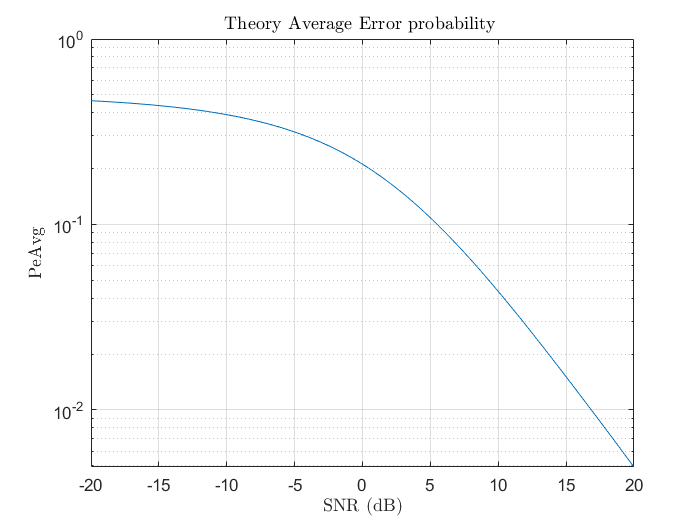

save pe4parta.mat 'Peavg'
semilogy(SNR_dB,Peavg );
grid on
xlabel(" SNR (dB)",'interpreter','latex');
ylabel("PeAvg",'interpreter','latex');
title("Theory Average Error probability ",'interpreter','latex');

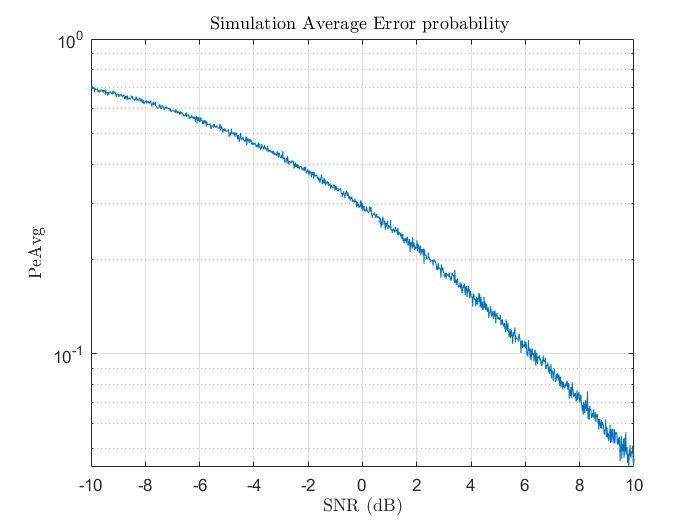

clc
clear all
a = 1;
N=1e4;
SNR_dB = linspace(-10, 10, N/8);
ForLen = length(SNR_dB);
x = randi([0,3],N,1);
xuse = zeros(N,1);
for i=1:N
    if(x(i)==0)
        xuse(i) = a*(1+1j);
    end
    if(x(i)==1)
        xuse(i) = a*(-1+1j);
    end
    if(x(i)==3)
        xuse(i) = -a*(1+1j);
    end
    if(x(i)==2)
        xuse(i) = a*(1-1j);
    end
end

Pe = zeros(1,length(SNR_dB));
for i=1:ForLen
    H = sqrt(1/2)*(randn(N,1)+1j*randn(N,1));
    N0 = a^2./10.^(SNR_dB(i)/10);
    W = sqrt(N0/2)*(randn(N,1) + 1j.*randn(N,1));
    Y = H.*xuse + W;
    Yp = Y.*conj(H)./abs(H);
    Ydecision = zeros(N,1);
    Erroneous = 0;
    for z=1:length(Yp)
     if (real(Yp(z))>0 && imag(Yp(z))>0)
        Ydecision(z) = a*(1+1j);
    end
    if (real(Yp(z))>0 && imag(Yp(z))<0)
        Ydecision(z) = a*(1-1j);
    end
    if (real(Yp(z))<0 && imag(Yp(z))>0)
        Ydecision(z) = a*(-1+1j);
    end
    if (real(Yp(z))<0 && imag(Yp(z))<0)
        Ydecision(z)= -a*(1+1j);
    end
    end
   ErDetArr = xuse+Ydecision;
   temp = numel(ErDetArr) - nnz(ErDetArr);
   ErDetArr(ErDetArr==2*a*(1+1j))=0 ;
   ErDetArr(ErDetArr==2*a*(-1+1j))=0;
   ErDetArr(ErDetArr==2*a*(1-1j))=0;
   ErDetArr(ErDetArr==-2*a*(1+1j))=0;
   temp2 = numel(ErDetArr) - nnz(ErDetArr);
   Erroneous = 2*temp + (numel(ErDetArr) - temp2 );
   Pe(i) = Erroneous./N;
end
semilogy(SNR_dB,Pe);
grid on
xlabel(" SNR (dB)",'interpreter','latex');
ylabel("PeAvg",'interpreter','latex');
title("Simulation Average Error probability ",'interpreter','latex');

semilogy(SNR_dB,Pe );
grid on
xlabel(" SNR (dB)",'interpreter','latex');
ylabel("PeAvg",'interpreter','latex');
title("Simulation Average Error probability ",'interpreter','latex');

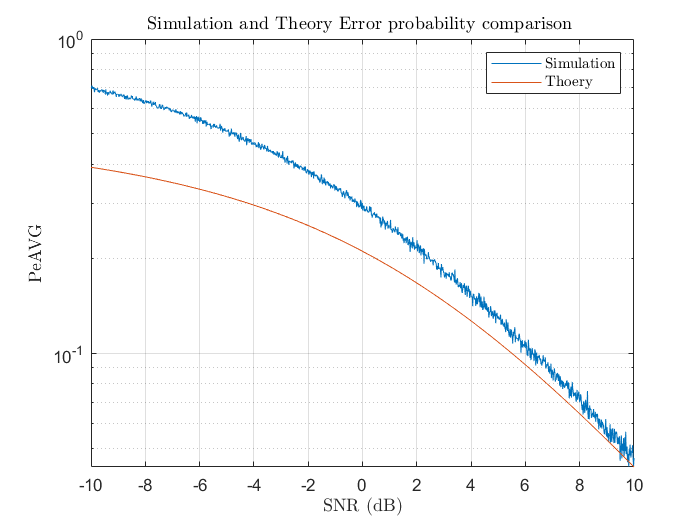

Peavg4 = load("pe4parta.mat");
Peavg4 = Peavg4.Peavg;
figure
semilogy(SNR_dB,Pe,SNR_dB,Peavg4 );
grid on
xlabel(" SNR (dB)",'interpreter','latex');
ylabel("PeAVG",'interpreter','latex');
title("Simulation and Theory Error probability comparison ",'interpreter','latex');
legend('Simulation','Thoery','interpreter','latex')

**Part b)**

clc
clear all
a = 1;
N=1e4;
SNR_dB = linspace(-20, 20, N/8);
ForLen = length(SNR_dB);
x = randi([0,3],N,1);
xuse = zeros(N,1);
for i=1:N
    if(x(i)==0)
        xuse(i) = a*(1+1j);
    end
    if(x(i)==1)
        xuse(i) = a*(-1+1j);
    end
    if(x(i)==3)
        xuse(i) = -a*(1+1j);
    end
    if(x(i)==2)
        xuse(i) = a*(1-1j);
    end
end

Pe = zeros(1,length(SNR_dB));
for i=1:ForLen
    H = sqrt(1/2)*(randn(N,1)+1j*randn(N,1));
    N0 = a^2./10.^(SNR_dB(i)/10);
    W = sqrt(N0/2)*(randn(N,1) + 1j.*randn(N,1));
    Y = H.*xuse + W;
    Yp = Y.*conj(H)./abs(H);
    Ydecision = zeros(N,1);
    Erroneous = 0;
    for z=1:length(Yp)
     if (real(Yp(z))>0 && imag(Yp(z))>0)
        Ydecision(z) = a*(1+1j);
    end
    if (real(Yp(z))>0 && imag(Yp(z))<0)
        Ydecision(z) = a*(1-1j);
    end
    if (real(Yp(z))<0 && imag(Yp(z))>0)
        Ydecision(z) = a*(-1+1j);
    end
    if (real(Yp(z))<0 && imag(Yp(z))<0)
        Ydecision(z)= -a*(1+1j);
    end
    end
   ErDetArr = xuse+Ydecision;
   temp = numel(ErDetArr) - nnz(ErDetArr);
   ErDetArr(ErDetArr==2*a*(1+1j))=0 ;
   ErDetArr(ErDetArr==2*a*(-1+1j))=0;
   ErDetArr(ErDetArr==2*a*(1-1j))=0;
   ErDetArr(ErDetArr==-2*a*(1+1j))=0;
   temp2 = numel(ErDetArr) - nnz(ErDetArr);
   Erroneous = 2*temp + (numel(ErDetArr) - temp2 );
   Pe(i) = Erroneous./N;
end
semilogy(SNR_dB,Pe);
grid on
xlabel(" SNR (dB)",'interpreter','latex');
ylabel("PeAvg",'interpreter','latex');
title("Simulation Average Error probability ",'interpreter','latex');

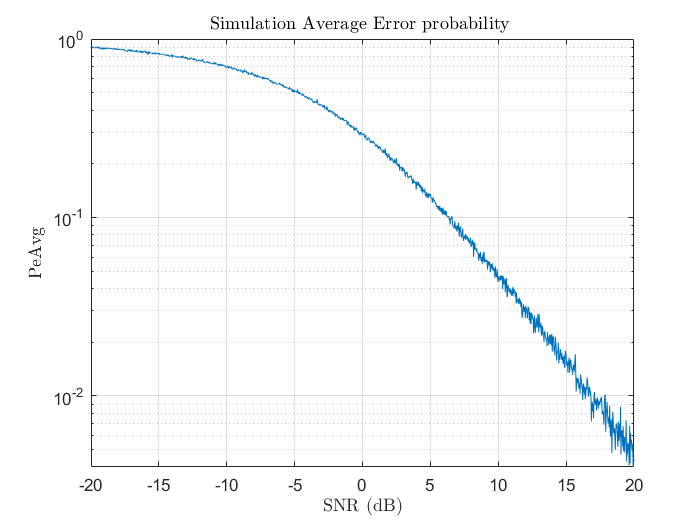

Peavg2 = load("pe2partb.mat");
Peavg2 = Peavg2.Pe;

figure
semilogy(SNR_dB,Pe,SNR_dB,Peavg2 );
grid on
xlabel(" SNR (dB)",'interpreter','latex');
ylabel("PeAVG",'interpreter','latex');
title("Simulation Error probability comparison ",'interpreter','latex');
legend('Pe of Question 4','Pe of Question 2','interpreter','latex')
hold off

**Question 5**

**Part b)**

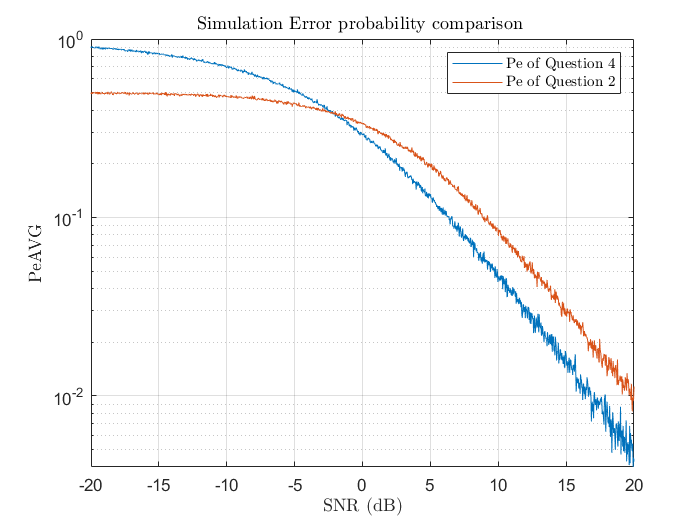

%Thoeretical
syms j
N=1e4;

SNR_dB = linspace(-10, 10, N/8);
ForLen = length(SNR_dB);
Larray = [1,2,3,4,5];
Llength = length(Larray);
PeTheory = zeros(ForLen,Llength);
for L=1:Llength
    for i=1:ForLen
    beta = sqrt(10.^(SNR_dB(i)/10)/(1+10.^(SNR_dB(i)/10)));
    PeTheory(i,L) = symsum( ((((1+beta)/2)^j).*(nchoosek(L+j-1,j))),j,0,L-1)*(((1-beta)/2)^L);
    end
end
PeTheory

figure
semilogy(SNR_dB,PeTheory(:,1),SNR_dB,PeTheory(:,2),SNR_dB,PeTheory(:,3),SNR_dB,PeTheory(:,4),SNR_dB,PeTheory(:,5))
grid on
xlabel(" SNR (dB)",'interpreter','latex');
ylabel("PeAVG",'interpreter','latex');
title("Theoretical Error probability for diversity ",'interpreter','latex');
legend('L=1','L=2','L=3','L=4','L=5','interpreter','latex')

PeTheory =     0.3492    0.2807    0.2340    0.1986    0.1704
    0.3490    0.2804    0.2336    0.1982    0.1700
    0.3487    0.2800    0.2332    0.1978    0.1696
    0.3485    0.2797    0.2328    0.1974    0.1692
    0.3482    0.2793    0.2324    0.1969    0.1687
    0.3480    0.2790    0.2320    0.1965    0.1683
    0.3477    0.2786    0.2316    0.1961    0.1679
    0.3475    0.2783    0.2313    0.1957    0.1675
    0.3472    0.2780    0.2309    0.1953    0.1670
    0.3470    0.2776    0.2305    0.1949    0.1666


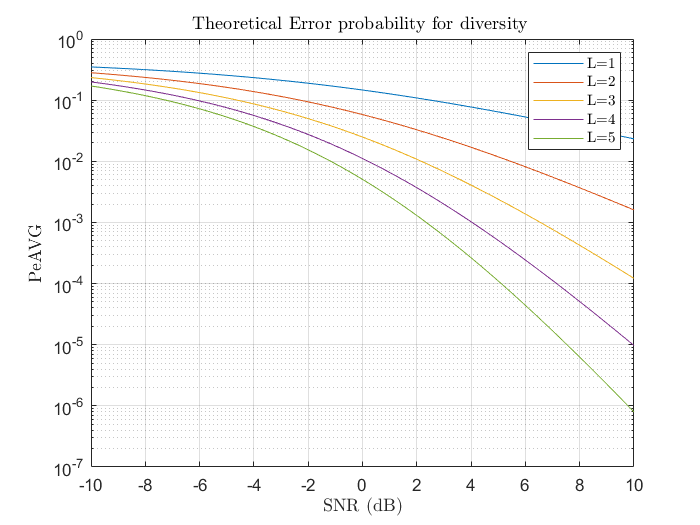

%Sim
%clear all
N=1e4;
SNR_dB = linspace(-10, 10, N/8);
ForLen = length(SNR_dB);
Larray = [1,2,3,4,5];
Llength = length(Larray);
Pesim = zeros(ForLen,Llength);

x = 2*bit_gen(N,2)-1;
for L=1:Llength
    for i=1:ForLen
    H = sqrt(1/2).*(randn(N,L)+1j*randn(N,L));
    N0 = 1^2./10.^(SNR_dB(i)/10);
    W = sqrt(N0/2)*(randn(N,L) + 1j*randn(N,L));
    Y = H.*x + W;
    alpha = sqrt(((abs(H)).^2)/N0).*exp(-1j*(angle(H)));
    YDet = sum(Y.*alpha,2);
    Erroneous = real(YDet).*x<0;
    Pesim(i,L) = sum(Erroneous,'all')./N;
    end
end

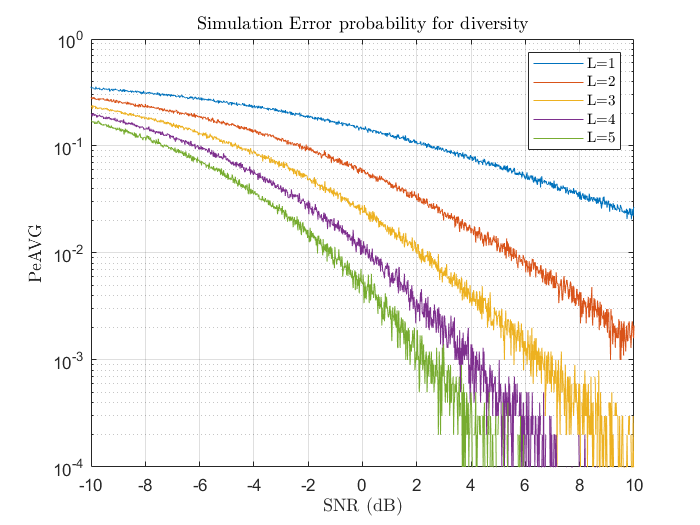

figure
semilogy(SNR_dB,Pesim(:,1),SNR_dB,Pesim(:,2),SNR_dB,Pesim(:,3),SNR_dB,Pesim(:,4),SNR_dB,Pesim(:,5))
grid on
xlabel(" SNR (dB)",'interpreter','latex');
ylabel("PeAVG",'interpreter','latex');
title("Simulation Error probability for diversity",'interpreter','latex');
legend('L=1','L=2','L=3','L=4','L=5','interpreter','latex')

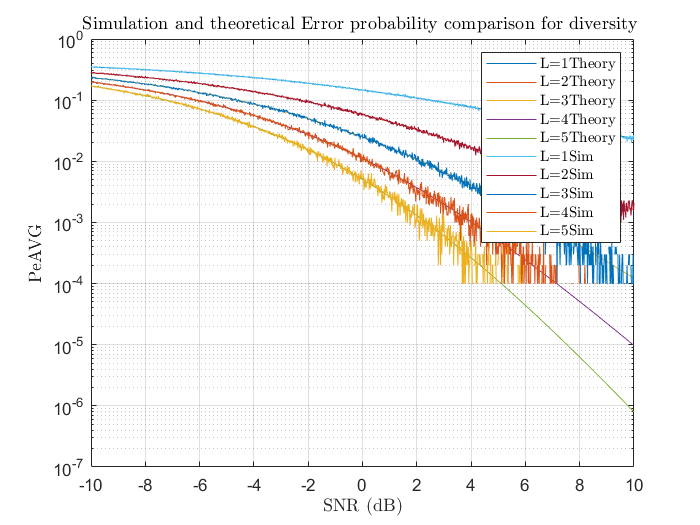

figure
semilogy(SNR_dB,PeTheory(:,1),SNR_dB,PeTheory(:,2),SNR_dB,PeTheory(:,3),SNR_dB,PeTheory(:,4),SNR_dB,PeTheory(:,5),SNR_dB,Pesim(:,1),SNR_dB,Pesim(:,2),SNR_dB,Pesim(:,3),SNR_dB,Pesim(:,4),SNR_dB,Pesim(:,5))
grid on
xlabel(" SNR (dB)",'interpreter','latex');
ylabel("PeAVG",'interpreter','latex');
title("Simulation and theoretical Error probability comparison for diversity ",'interpreter','latex');
legend('L=1Theory','L=2Theory','L=3Theory','L=4Theory','L=5Theory','L=1Sim','L=2Sim','L=3Sim','L=4Sim','L=5Sim','interpreter','latex')

**Question 6**

**Part b)**

clear all
a = 1;
M = 2;
N=1e4;
N2 = 2e4;
SNR_dB = linspace(-10, 15, 200);
ForLen = length(SNR_dB);
x1 = 2* bit_gen(N,2) -1 ;
x2 = 2*bit_gen(N,2) - 1;
Pe = zeros(1,length(SNR_dB));
Erroneous = zeros(1,length(SNR_dB));
for i = 1:ForLen
    for j=1:N
    H = sqrt(1/2)*(randn(M,1)+1j*randn(M,1));
    N0 = a^2./10.^(SNR_dB(i)/10);
    W = sqrt(N0/2)*(randn(M,1) + 1j.*randn(M,1));
    s = [x1(j);x2(j)];
    Hc = [H(1),H(2);conj(H(2)) -conj(H(1))];
    Y = Hc*s + W;
    Z = Hc'*Y;
    Zdecision = zeros(M,1);
    Zdecision(real(Z)>0)=a;
    Zdecision(real(Z)<0)=-a;
    Erroneous(i) = Erroneous(i) + sum(s~=Zdecision);
    end
    Pe(i) = Erroneous(i)/(N2);
end

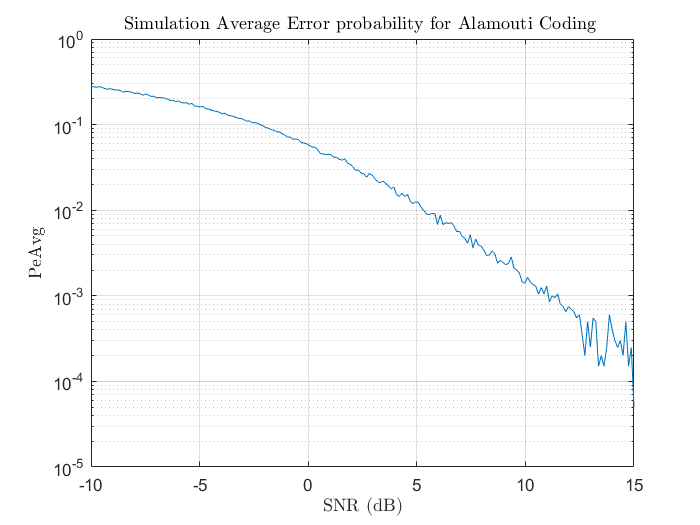

figure
semilogy(SNR_dB,Pe);
grid on
xlabel(" SNR (dB)",'interpreter','latex');
ylabel("PeAvg",'interpreter','latex');
title("Simulation Average Error probability for Alamouti Coding ",'interpreter','latex');